# Plane Elasticity: Triangular elements

A trianglular plate of thickness $t_{h} = 1\,\text{cm}$ with vertices, 

                    $v_{1} = (0,0)$, $v_{2} = (10,0)$, and $v_{3} = (5,10)$ 

(length units in cm), made with material with Young modulus $E = 30\times 10^{6}\,\text{N/cm}^{2}$ and Poisson's ratio $\nu = 0.3$, is fixed by the edge joining vertices $v_{1}$and $v_{2}$,  and subjected to a traction of modulus $\tau_{0} = 20\, \text{N/cm}^{2}$ in the normal direction along the edge joining the vertices $v_{2}$ and $v_{3}$ (see Figure). 

                      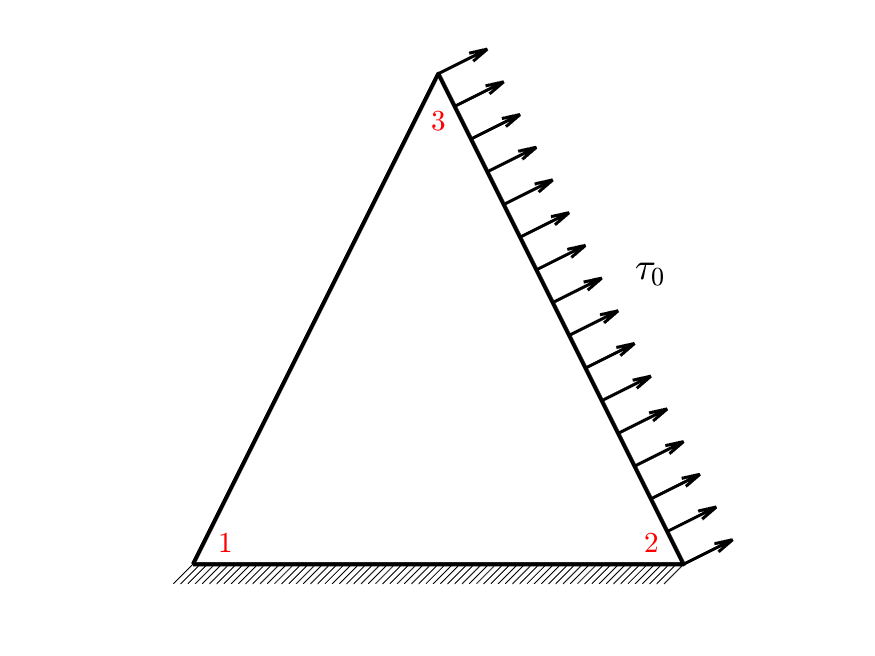

Using the FEM approach with this triangle as the only element, find the displacement of $v_{3}$ and the stress tensor.

See the practice at the [Numerical Factory](https://numfactory.upc.edu/numfactory/subjects/FEM/Elasticity/practices/P4.1/html/P4_1_PlaneElasticityTriang_en.html) (prof. Antonio Susín)

## Solution

#### Material properties

Thickness $t_{h} = 1\,\text{cm}$,Young Modulus $E = 30\times 10^{6}\,\text{N/cm}^{2}}$, Poisson's ratio $\nu = 0.3$. 

- $\texttt{modelProblem} = 1$: stress problem

- $\texttt{modelProblem} = 2$: strain problem

%Material properties
E=3.0e+7; %Young Modulus (N/cm^2)
nu=0.3; %Poisson's ratio (adimensional)
th=1.0;  % thickness (cm)
t=20; %traction force N/cm (in the normal direction of the 2nd edge).
modelProblem=1; %stress problem

switch modelProblem
    case 1
        c11=E/(1-nu^2);
        c22=c11;
        c12=nu*c11;
        c21=c12;
        c33=E/(2*(1+nu));
        fprintf('Plane stress problem\n')
    case 2
        th=1.0;
        c11=E*(1-nu)/((1+nu)*(1-2*nu));
        c22=c11;
        c12=c11*nu/(1-nu);
        c21=c12;
        c33=E/(2*(1+nu));
        fprintf('Plane strain problem\n')
    otherwise
        error('modelProblem should be 1 (stress) or 2 (strain)');
end

Plane stress problem



C=[c11, c12, 0; c21, c22, 0; 0, 0, c33];

#### Geometry

Set nodes and elements

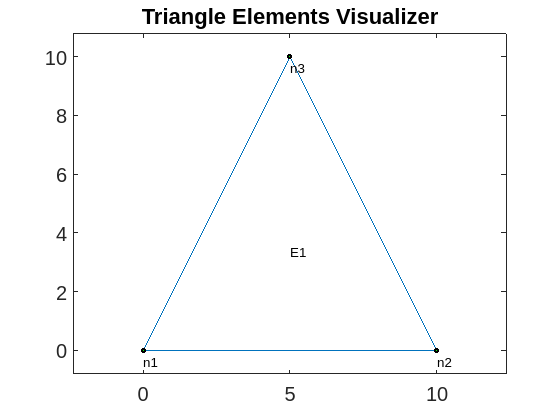

v1=[0,0];
v2=[10,0];
v3=[5,10];
nodes=[v1;v2;v3];
elem=[1,2,3];
numNod=size(nodes,1);
ndim=size(nodes,2);
numElem=size(elem,1);
numbering=1;
%plotElements(nodes,elem,numbering)
plotElementsOld(nodes,elem,numbering)

#### Computation of stiffness matrix: $K^{e} = \left(B^{e}\right)^{\top} C B^{e}$

beta=[v2(2)-v3(2),v3(2)-v1(2),v1(2)-v2(2)];
gamma=-[v2(1)-v3(1),v3(1)-v1(1),v1(1)-v2(1)];
%alpha=[v2(1)*v3(2)-v2(2)*v3(1),v3(1)*v1(2)-v3(2)*v1(1),v1(1)*v2(2)-v1(2)*v2(1)];
Area=1/2*det([ones(3,1),nodes]);
B=[beta(1),  0, beta(2), 0,     beta(3), 0; ...
   0 ,  gamma(1),0 ,   gamma(2),    0,  gamma(3); 
   gamma(1), beta(1), gamma(2), beta(2),gamma(3), beta(3)]/(2*Area);
K=th*Area*(B'*C*B)

K = 1.0e+07 *

    1.7926    0.5357   -1.5041   -0.0412   -0.2885   -0.4945
    0.5357    0.9890    0.0412   -0.1648   -0.5769   -0.8242
   -1.5041    0.0412    1.7926   -0.5357   -0.2885    0.4945
   -0.0412   -0.1648   -0.5357    0.9890    0.5769   -0.8242
   -0.2885   -0.5769   -0.2885    0.5769    0.5769         0
   -0.4945   -0.8242    0.4945   -0.8242         0    1.6484


#### Boundary conditions

edgeVector=(v3-v2)/norm(v3-v2);
normal=[edgeVector(2),-edgeVector(1)]; %unitary normal to the second edge
                                       %and pointing outwards the triangle
f=t*normal; %constant traction applied on normal vector direction

Plot traction vector (origin at the edge)

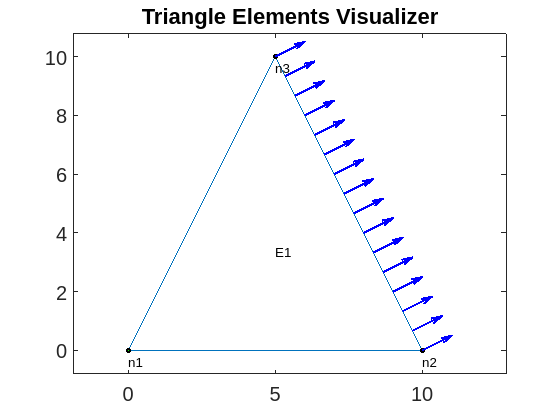

ndiv=15; %number of arrows in the plot
vini=v2;
vfin=v3;
scale=0.1*norm(vini-vfin)/t; %scale arrows according to t value
signe=1; %force orientation
plotElementsOld(nodes,elem,numbering);
plotEdgeConstantBC(vini,vfin,t,ndiv,scale,signe,'filled',...
    'Color','blue','LineWidth',1.5); %Plot Natural B.C.: 

Natural B.C.: constant traction on the second edge of the traiangle

Q=0.5*norm(v3-v2)*[0;0;f(1);f(2);f(1);f(2)]; %traction force in N/cm^2

Essential B.C.: the plate is fixed at the edge joining vertes $1$ and $2$, so $u_{1} = v_{1} = u_{2} = v_{2} = 0$.

fixedNod=[];
%nod 1;
nNod=1; 
fixedNod=[fixedNod,ndim*nNod-1]; %u1x=0
fixedNod=[fixedNod,ndim*nNod];   %u1y=0

%nod 2;
nNod=2; 
fixedNod=[fixedNod,ndim*nNod-1]; %u2x=0
fixedNod=[fixedNod,ndim*nNod];   %u2y=0
%

u=zeros(ndim*numNod,1);
u(fixedNod)=0.0;

#### Reduced system

freeNod=setdiff(1:ndim*numNod,fixedNod);

%Fm=F(freeNod)-K(freeNod,fixedNod)*u(fixedNod); 
     %Here u(fixedNod)=0,so this is not necessary
                                                
%Fm=Fm+Q(freeNod); 
     %F=0: no "internal forces(e.g. the body weight) are
     %taken into account. So we can set, directly Fm=Q(freeNod)
Fm=Q(freeNod);
Km=K(freeNod,freeNod);

%Solve the reduced system
um=Km\Fm;
u(freeNod)=um;

Qm=Q(freeNod);
Km=K(freeNod,freeNod);

%Solve the reduced system
um=Km\Qm;
u(freeNod)=um;

#### Post Process

Compute stress and strain from the displacements $\epsilon^{e} = B^{e} u^{e}$, and $\sigma^{e} = C\epsilon^{e}$

strain=B*u;
stress=C*strain;
vonMises=sqrt(stress(1)^2+stress(2)^2-stress(1)*stress(2) ...
    +3*stress(3)^2);

Show table with the displacements

format short e
displTable=table((1:numNod)',nodes(:,1),nodes(:,2),...
                  u(1:2:end),u(2:2:end),...
                  'VariableNames',{'Nod','X','Y','UX','UY'});
displTable

displTable = 3×5 table
       Nod            X             Y             UX            UY    
    __________    __________    __________    __________    __________
    1.0000e+00    0.0000e+00    0.0000e+00    0.0000e+00    0.0000e+00
    2.0000e+00    1.0000e+01    0.0000e+00    0.0000e+00    0.0000e+00
    3.0000e+00    5.0000e+00    1.0000e+01    1.7333e-05    3.0333e-06

Show table with strains

format short e
strain= strain';
strainTable=table((1:numElem)',strain(:,1),strain(:,2),strain(:,3),...
                  'VariableNames',{'Elem','EX','EY','Exy'});
strainTable

strainTable = 1×4 table
       Elem           EX            EY           Exy    
    __________    __________    __________    __________
    1.0000e+00    0.0000e+00    3.0333e-07    1.7333e-06

Show table with stress

format short e
stress=stress';
stressTable=table((1:numElem)',stress(:,1),stress(:,2),stress(:,3),...
                  vonMises,...
                  'VariableNames',{'Elem','SX','SY','SXY','VM'});                     
%And show the stress just for the last 10 results
stressTable

stressTable = 1×5 table
       Elem           SX            SY           SXY            VM    
    __________    __________    __________    __________    __________
    1.0000e+00    3.0000e+00    1.0000e+01    2.0000e+01    3.5763e+01

Graphical output: displacements

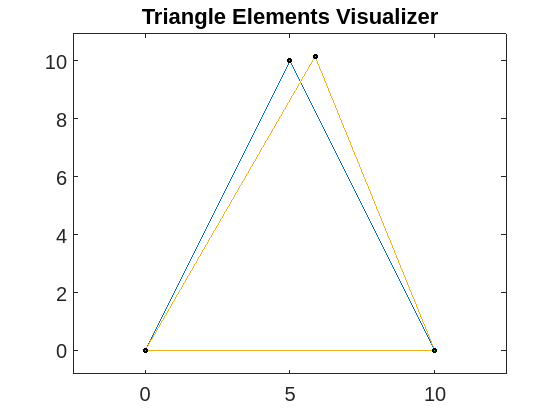

esc=5.0e4;
plotPlaneNodElemDespl(nodes,elem,u,esc);

## Exercise 

(See the practice guide at the [Numerical Factory](https://numfactory.upc.edu/numfactory/subjects/FEM/Elasticity/practices/P4.1/html/P4_1_PlaneElasticityTriang_en.html)). Build the function